# **Bivariate normal density**

## ** Using **`meshgrid`

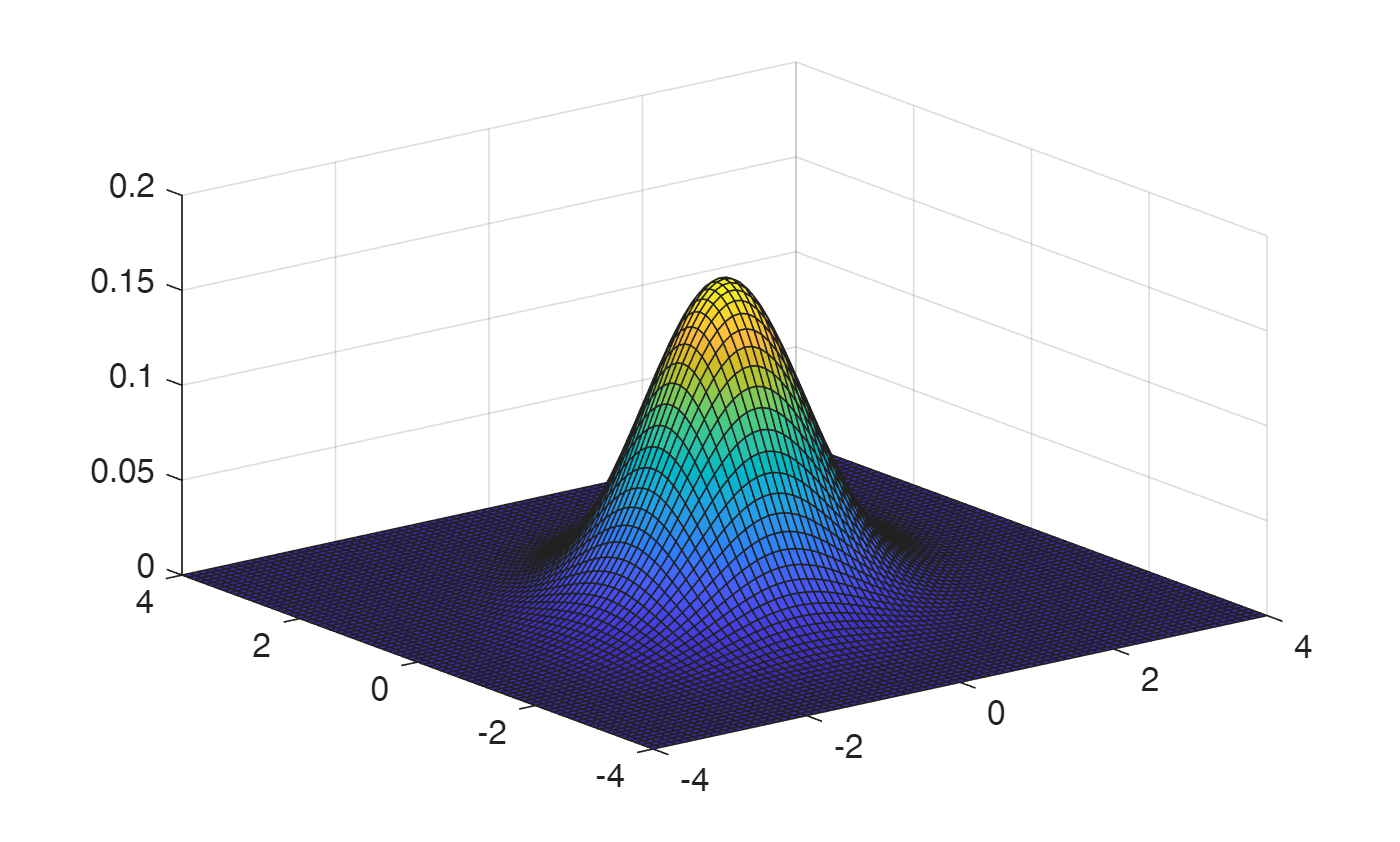

 rho=0.3;
seqx=(-4:0.1:4);
[x,y]=meshgrid(seqx);
dens2=(1/(2*pi*sqrt(1-rho^2)))...
    *exp(-(1/(2*(1-rho^2)))*(x.^2+y.^2-2*rho*x.*y));
surf(x,y,dens2)

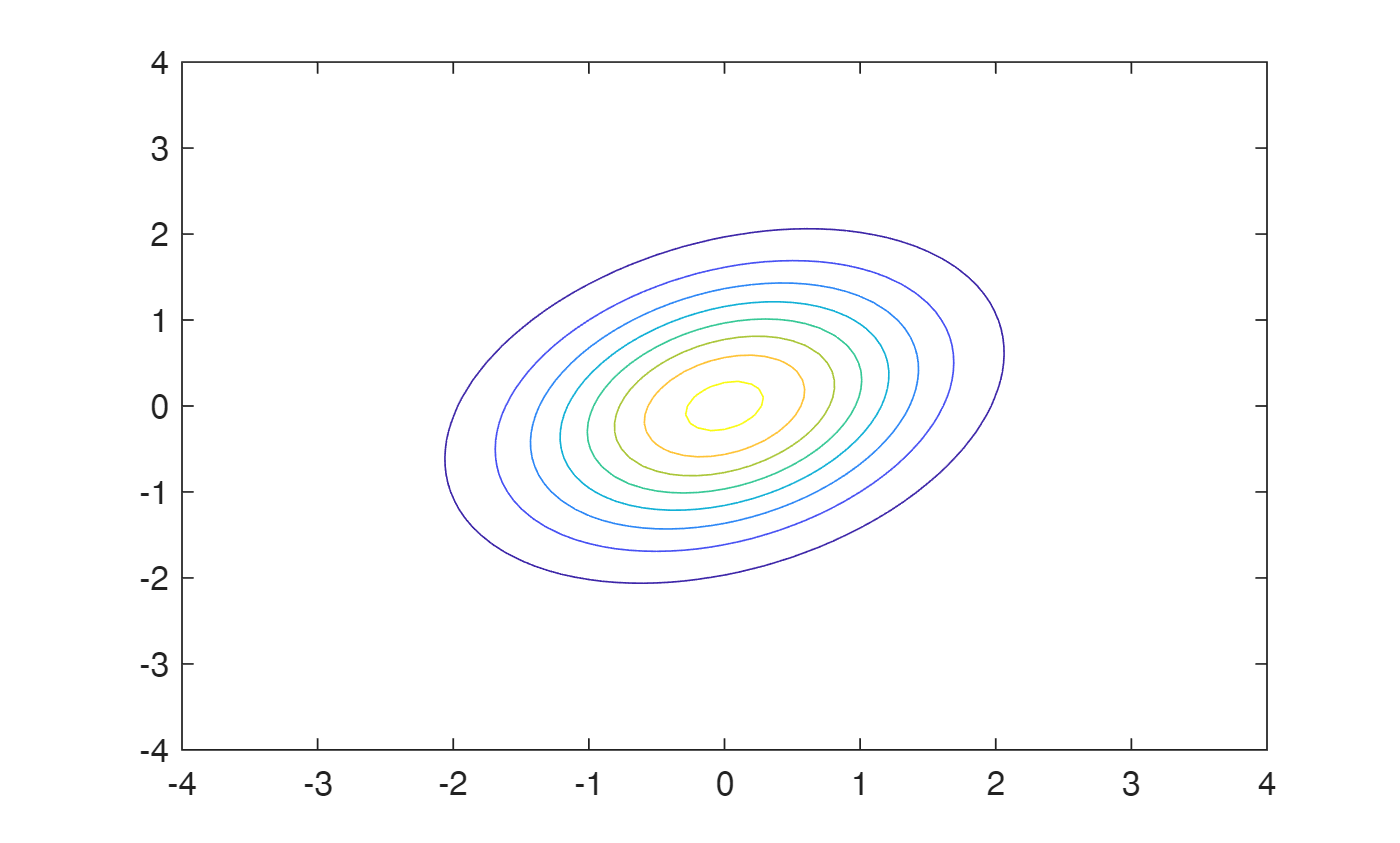

contour(x,y,dens2)

## Without for loops 

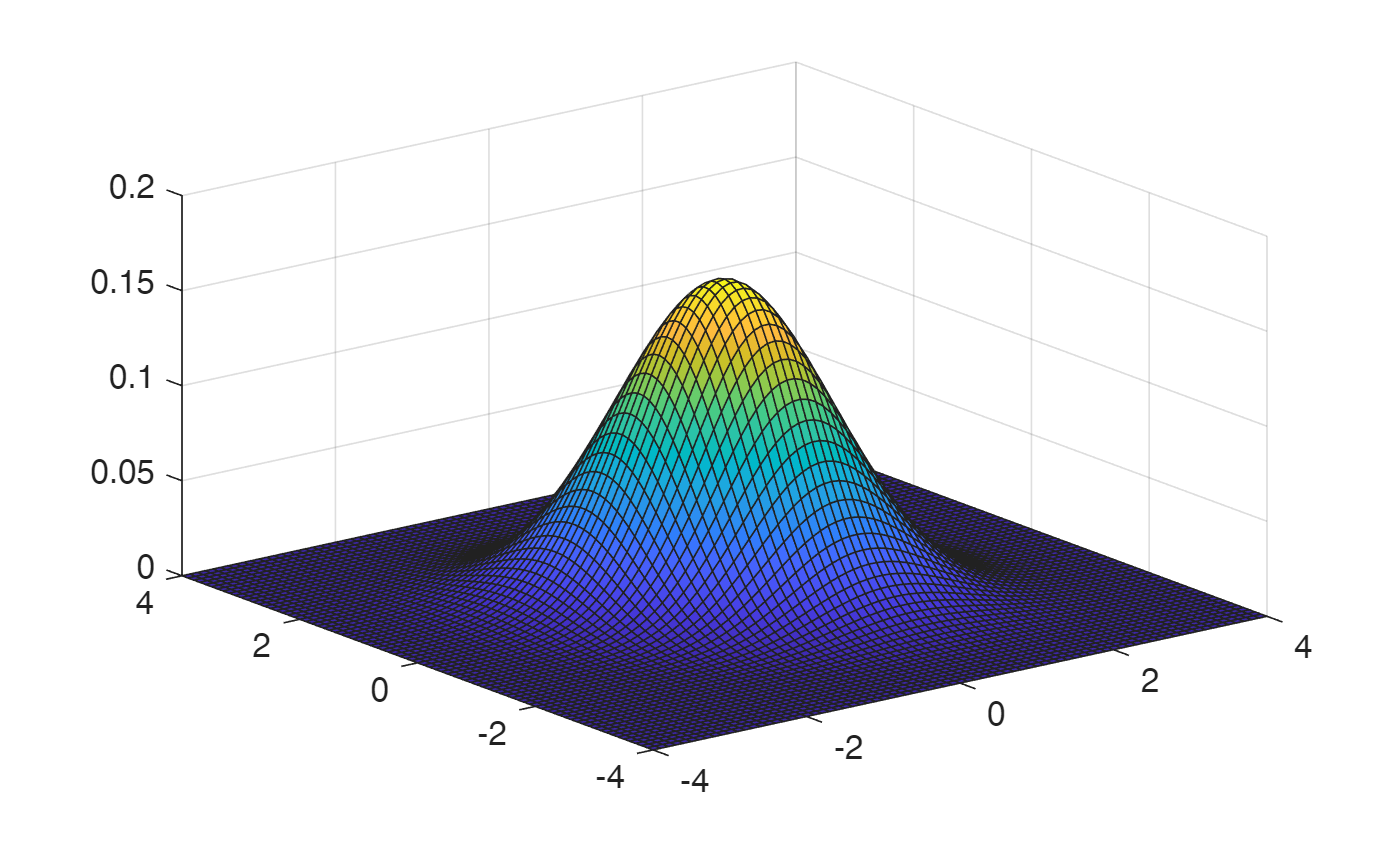

rho=-0.3;
seqx=(-4:0.1:4)'; 
seqy=seqx'; 
%  seqx * seqy ha dimnsion length(seqx)-by-length(seqy). The generic
%  element  is seqx(i)*seqy(j) Similarly seqx+seqy is a matrix of size
% length(seqx)-by-length(seqy) whose generic element is seqx(i)+seqy(j)
dens1=(1/(2*pi*sqrt(1-rho^2)))...
    *exp(-(1/(2*(1-rho^2)))*(seqx.^2+seqy.^2-2*rho*seqx*seqy));
surf(seqx,seqy,dens1)

## Using two foor loops

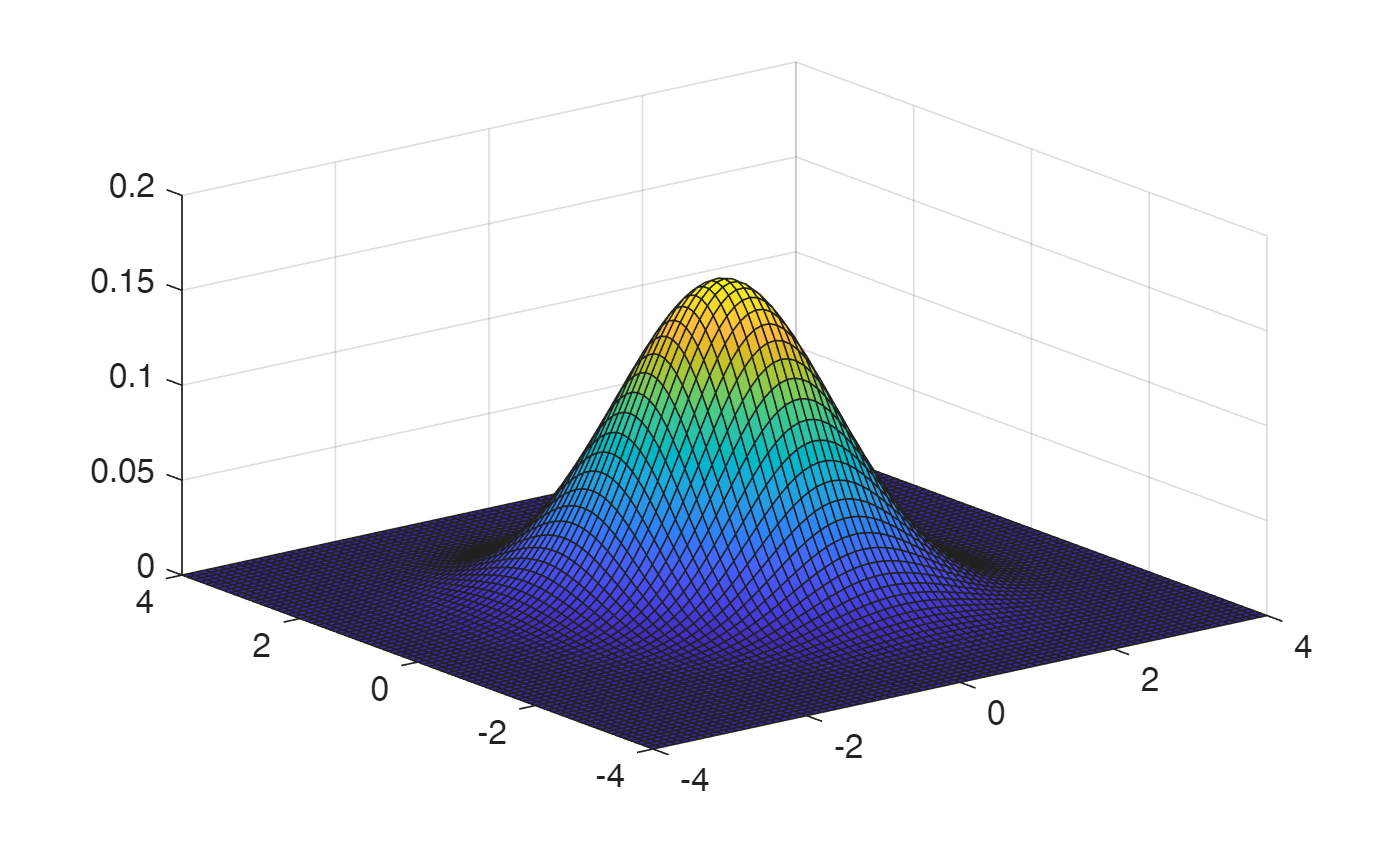

seq=-4:0.1:4;
lseq=length(seq);
dens=zeros(lseq,lseq);

rho=-0.3;
for i=1:lseq
    for j=1:lseq
        dens(i,j)=(1/(2*pi*sqrt(1-rho^2)))...
            *exp(-(1/(2*(1-rho^2)))*(seq(i)^2+seq(j)^2-2*rho*seq(i)*seq(j)));
    end
end

surf(seq,seq,dens)

## Implementation of the quadratic form

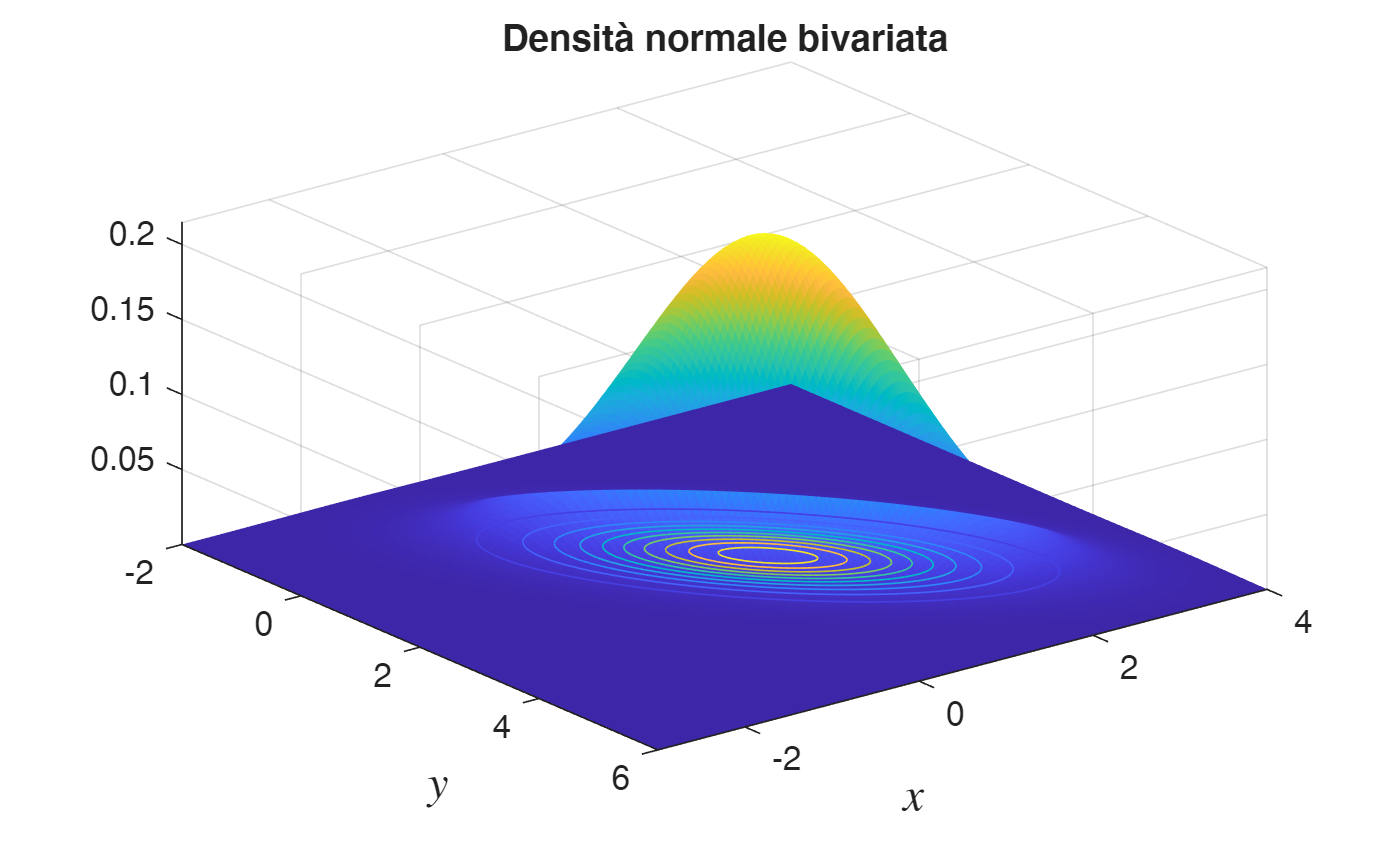

mu    = [1; 2];
Sigma = [0.8 0.7; 0.7 1.3];
% The grid is constructed (all combinations of x and y coordinates).
seqx=-3:0.05:4; lx=length(seqx);
seqy=-2:0.05:6; ly=length(seqy);
[X,Y] = meshgrid(seqx,seqy); % X e Y hanno dimensione ly-by-lx
% const = factor which multiplies exp
const = (1/sqrt(2*pi))^2/sqrt(det(Sigma));
% The density is computed for each point of the grid
% xtilde = ly*lx - by - 2
xtilde = [X(:)-mu(1) Y(:)-mu(2)];
formQuad=diag(xtilde*(Sigma\(xtilde')));

formQuadMatrix=reshape(formQuad,ly,lx);
% pdf contains the density
pdf = const*exp(-0.5*formQuadMatrix);

% surfc also allows displaying contour lines
surfc(X, Y, pdf, 'LineStyle', 'none');
title('Densità normale bivariata')
xlabel('$x$', 'Interpreter', 'latex','FontSize',14);
ylabel('$y$', 'Interpreter', 'latex','FontSize',14);
view([38 -39]);

## Contours of the quadratic form (Exercise 5.13)

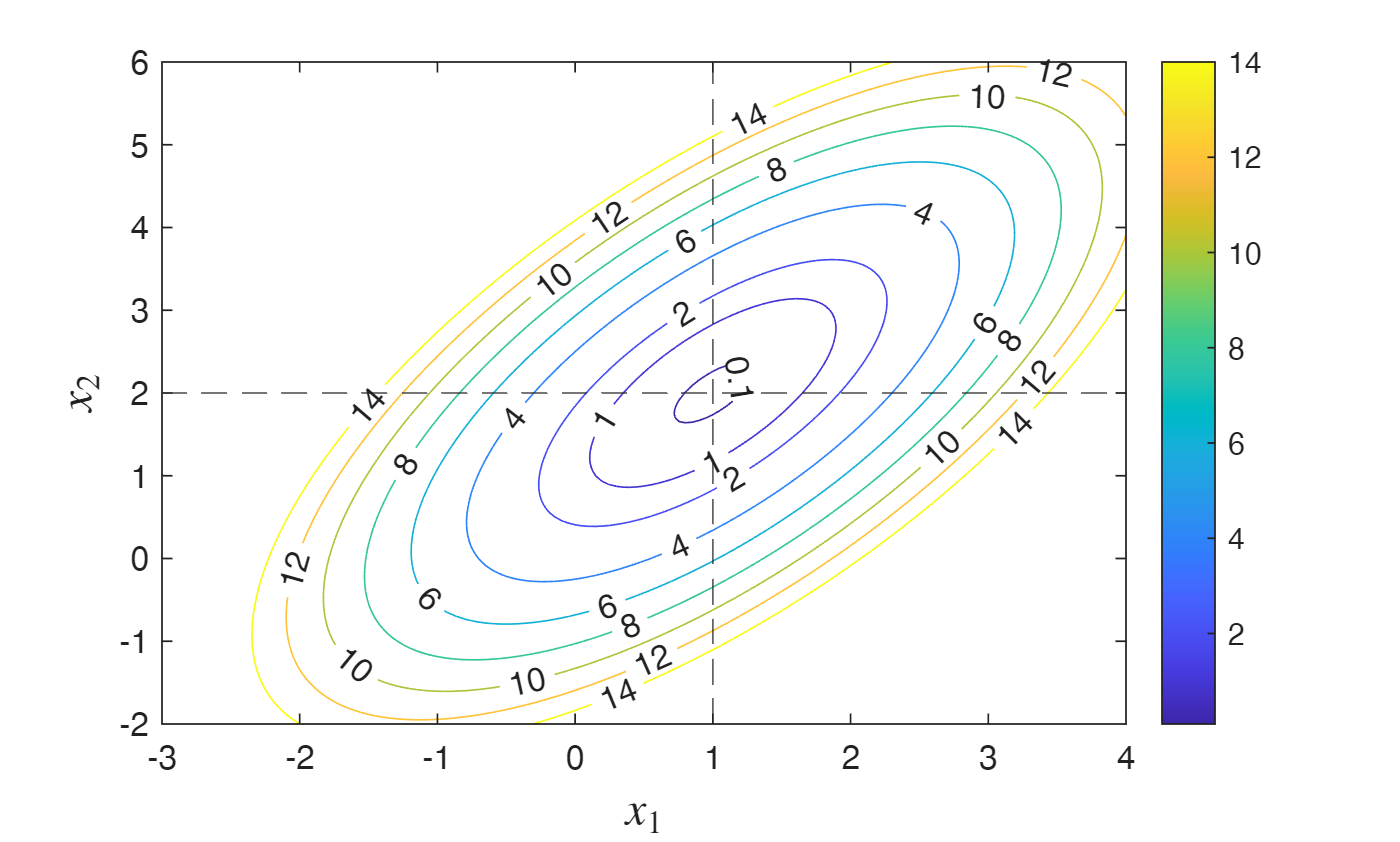

figure
contour(X,Y,formQuadMatrix,[0.1 1 2:2:14],'ShowText','on')
xline(mu(1),'--'); yline(mu(2),'--')
xlabel('$x_1$','Interpreter','latex','FontSize',14);
ylabel('$x_2$','Interpreter','latex','FontSize',14);
colorbar